# Create and Customize Animated Line Plots

Animated line plots are line plots that have data added to the plot over time.

### Create Wave Data

Use a helper function to generate data for a sine and cosine wave.

[x,y1,y2] = createData();

### Basic Animated Line Plot

Create an animated line object. Use `addpoints` in a for loop to iterate over the vectors x and y1 and add the data points to the animated line handle. Use `drawnow` to update the figure, and specify *'limitrate'  *to control how often the figure is updated.

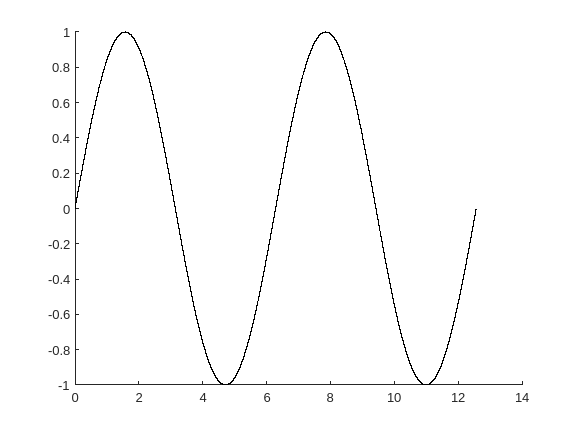

h = animatedline;

% Iterate over the vectors and use addpoints, drawnow to animate line
for k = 1:length(x)
    addpoints(h,x(k),y1(k)); % Add points to the animated line 
    drawnow limitrate        % Use limitrate to speed up animation
end

## Customization

### Specify Axis Limits, Customize Line Type and Color

To avoid the changing axes limits during the animation, specify the axes for the figure during initialization. In addition, customize the line appearance by using *Color *and *LineWidth* Name, Value pair arguments to `animatedline`.

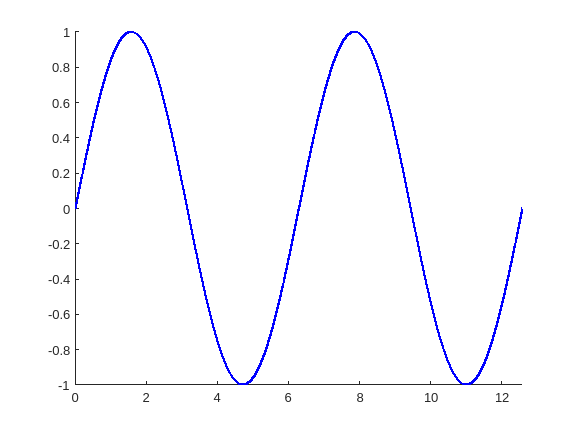

LineColor = 'b';
LineWidth = 2;

figure
axis([0,4*pi,-1,1]);
h1 = animatedline(...
    "Color",LineColor,...   % Specify line color
    "LineWidth",LineWidth); % Specify line width

for k = 1:length(x)
    addpoints(h1,x(k),y1(k));
    drawnow limitrate
end

### Animate Multiple Lines in One Axes

To animate multiple lines on one axes, simply add points to both animated lines in the same for loop.

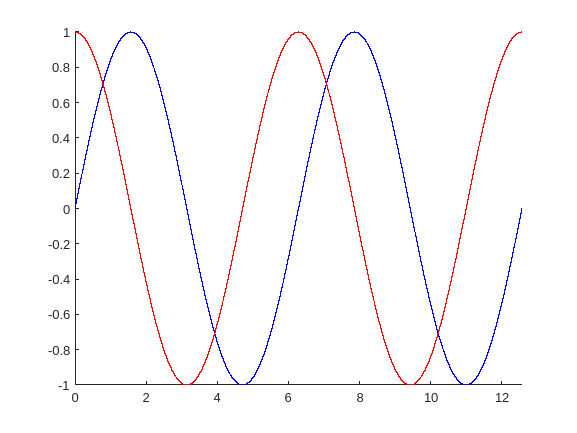

figure 
h2 = animatedline("Color",'b'); 
h3 = animatedline("Color",'r');
axis([0,4*pi,-1,1]) 

for k = 1:length(x)
  addpoints(h2,x(k),y1(k)) % Add points to animated line #1
  addpoints(h3,x(k),y2(k)) % Add points to animated line #2
  drawnow limitrate
end

### Animate Lines in Multiple Axes

To animate multiple lines on different axes, simply add points to both animated lines in the same for loop. Use `tiledlayout` and `nexttile` to specify the axes on which each plot should appear.

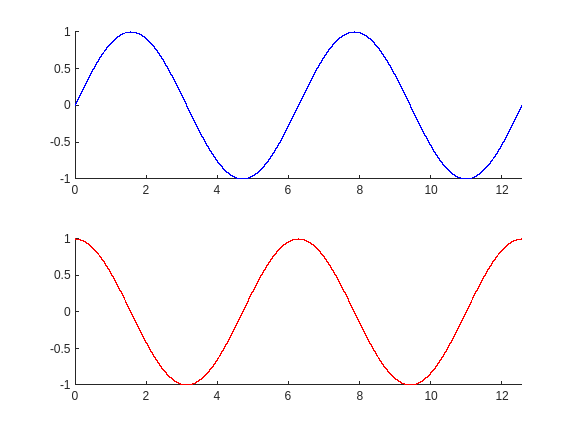

figure 
tiledlayout("flow")
nexttile
h4 = animatedline("Color",'b'); 
axis([0,4*pi,-1,1]) 

nexttile
h5 = animatedline("Color",'r');
axis([0,4*pi,-1,1]) 

for k = 1:length(x)
  addpoints(h4,x(k),y1(k)) 
  addpoints(h5,x(k),y2(k)) 
  drawnow limitrate 
end

### Control Animation Speed

For better control over the animation speed, use the *tic *and *toc *commands to control how much time passes between the screen updates. Specify the time interval between updating the plot. A longer interval leads to a faster animation.

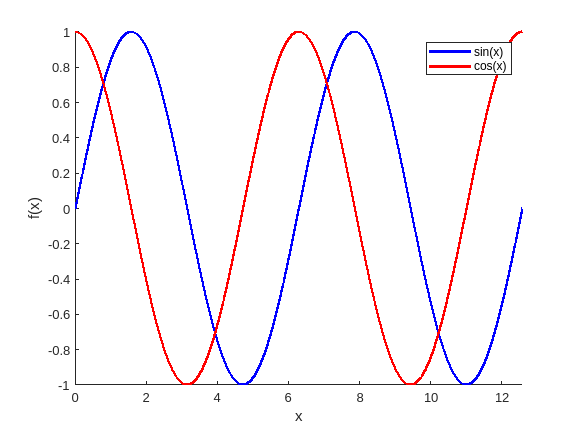

timeInterval = 0.1;

figure 
h7 = animatedline("Color",'b',"LineWidth",2); 
h8 = animatedline("Color",'r',"LineWidth",2);
axis([0,4*pi,-1,1]) 
xlabel("x"); ylabel("f(x)");
legend("sin(x)","cos(x)");

a = tic; % start timer
for k = 1:length(x)
    addpoints(h7,x(k),y1(k))
    addpoints(h8,x(k),y2(k))
    b = toc(a); % check timer
    if b > (timeInterval)
        drawnow
        a = tic; % reset timer after updating
    end
end

drawnow % draw final frame

## **Additional Information**

### **Get All AnimatedLine Properties **

Graphics objects in MATLAB have many properties. To see all the properties of an AnimatedLine, uncomment the following code. View or modify these properties using dot notation.

% get(h)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[animatedline](https://www.mathworks.com/help/matlab/ref/animatedline.html)

### Helper Functions

This function generates x, y1 and y2 data with the following relationships: $\textrm{y1}\;=\;\sin \left(x\right);\;\textrm{y2}\;=\;\cos \left(x\right)$.

function [x, y1, y2] = createData()
    x = linspace(0,4*pi,100000);
    y1 = sin(x);
    y2 = cos(x);
end

Copyright (c) 2021, The MathWorks, Inc.